1.1. plot three periods of the 1KHz sine wave

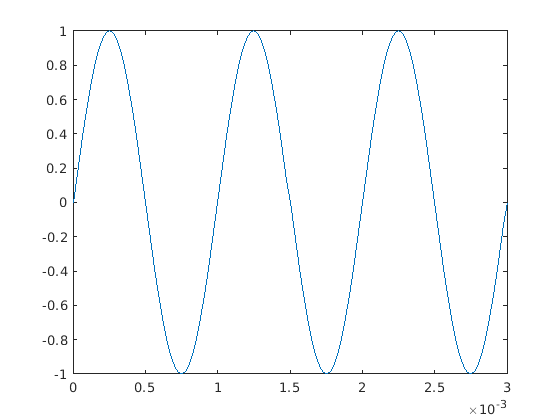

T=1;
Fs = 48000;
N = T*Fs;
t = 0 : 1/Fs : T;
Fn = 1000;
y = sin(Fn*2*pi*t);
plot(t,y);
axis([0 48/48000*3 -1 1])

1.2

a. 1KHz sine wave

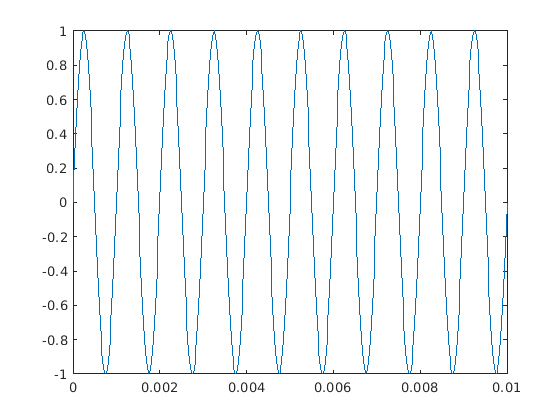

T=0.01;
Fs = 48000;
N = T*Fs;
t = 0 : 1/Fs : T;
Fn = 1000;
y = sin(Fn*2*pi*t);
% sound(y,Fs);
plot(t, y);

b. 500Hz sine wave

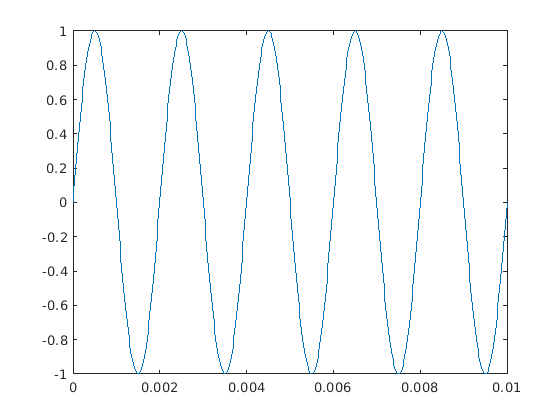

T=0.01;
Fs = 48000;
N = T*Fs;
t = 0 : 1/Fs : T;
Fn = 500;
y = sin(Fn*2*pi*t);
% sound(y,Fs);
plot(t, y);

c. 2KHz sine wave

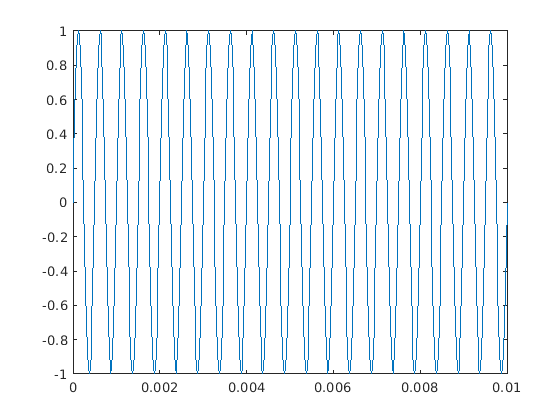

T=0.01;
Fs = 48000;
N = T*Fs;
t = 0 : 1/Fs : T;
Fn = 2000;
y = sin(Fn*2*pi*t);
% sound(y,Fs);
plot(t, y);

d. 10KHz sine wave

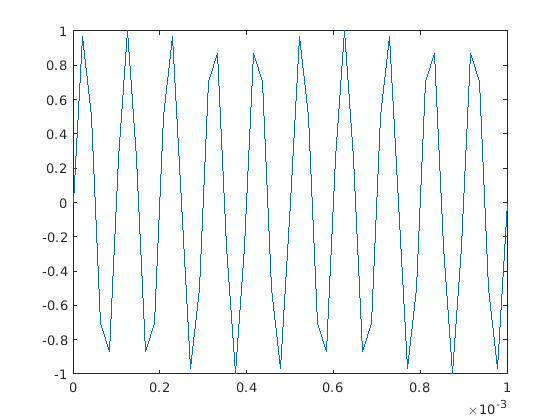

T=0.001;
Fs = 48000;
N = T*Fs;
t = 0 : 1/Fs : T;
Fn = 10000;
y = sin(Fn*2*pi*t);
% sound(y,Fs);
plot(t, y);

d. doubling voltage

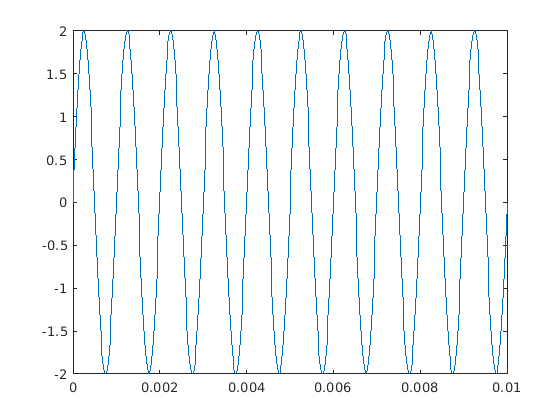

T=0.01;
Fs = 48000;
N = T*Fs;
t = 0 : 1/Fs : T;
Fn = 1000;
y = sin(Fn*2*pi*t)*2;
% sound(y,Fs);
plot(t, y);

1.3.

prep: signal loading section

[bass, fs] = audioread('bass.wav');
guitar = audioread('guitar.wav');
drums = audioread('drums.wav');

a. guitar signal duration

length(guitar)/fs

ans = 104.1516

b. synthesis signal 

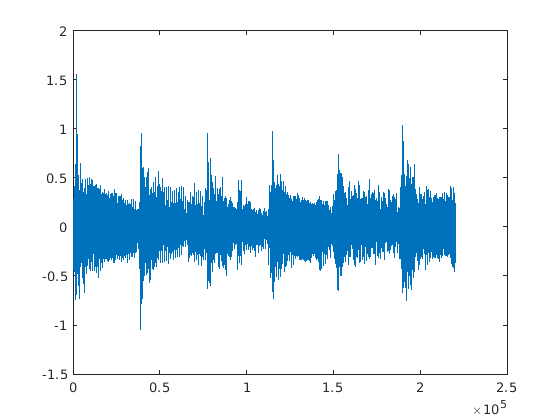

duration = 5;
b = bass(1:fs*duration);
g = guitar(1:fs*duration);
d = drums(1:fs*duration);
comp = b+g+d;
t = 0:1:fs*duration-1;
plot(t, comp);

c. increasing sound signal

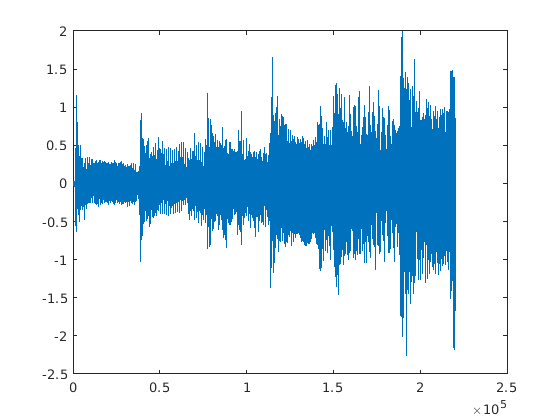

grad = (linspace(0,5,fs*duration)).';
syn_g = grad.*g;
in_comp = b + d +syn_g;
plot(t,in_comp);